**FIRST READ THE DATA SET (CSV FORMAT)**

clc %clears the command window
close all %close all windows
clear all %clears the workspace

Path = '/Users/mac/Desktop/FYP/Code and Data/Data Collection/';
warning("off")

colaccX = 3;
colaccY = 4;
colaccZ = 5;

colgyroX = 10;
colgyroY = 11;
colgyroZ = 12;

colgravX = 21;
colgravY = 22;
colgravZ = 23;

M = 32;

## **Backhands (my data)**

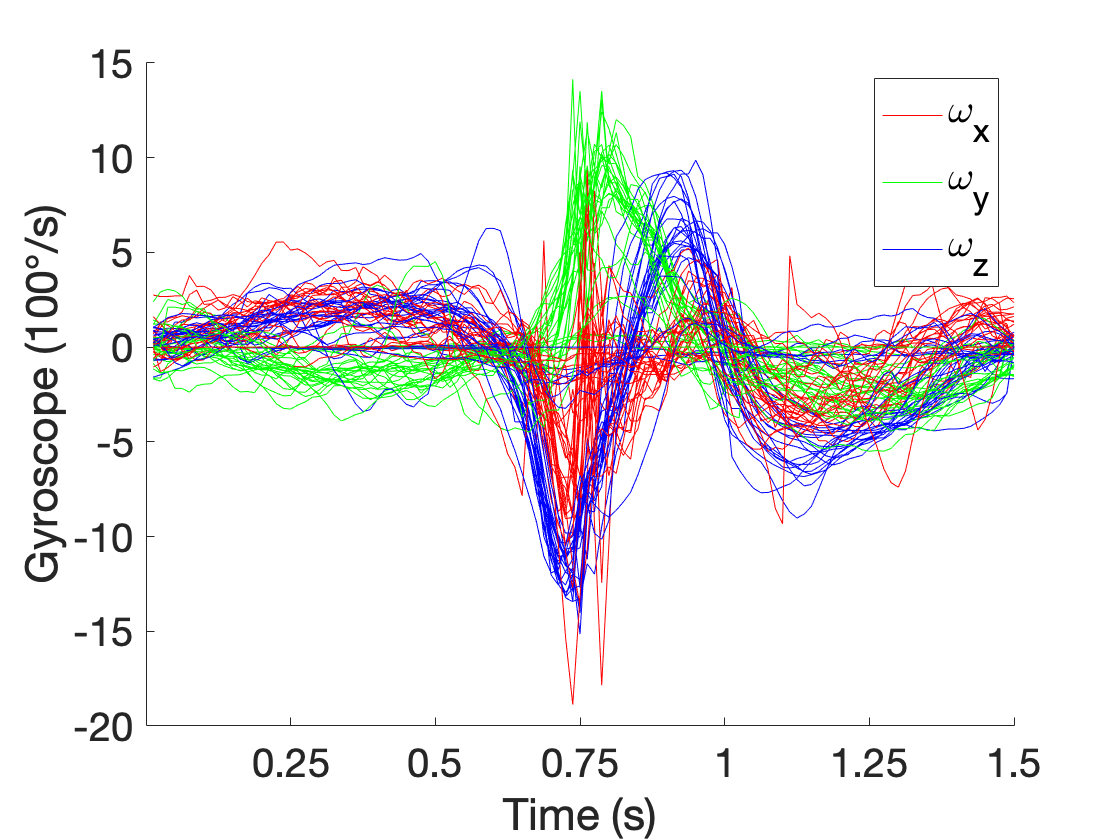

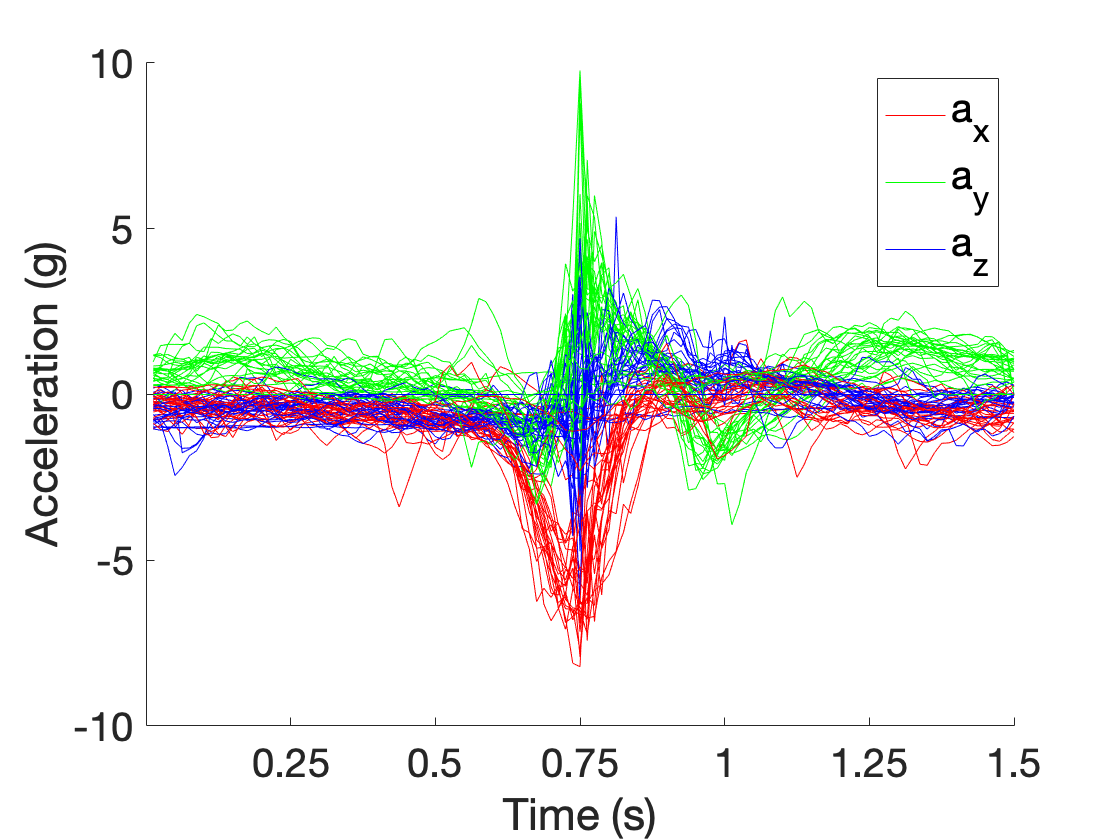

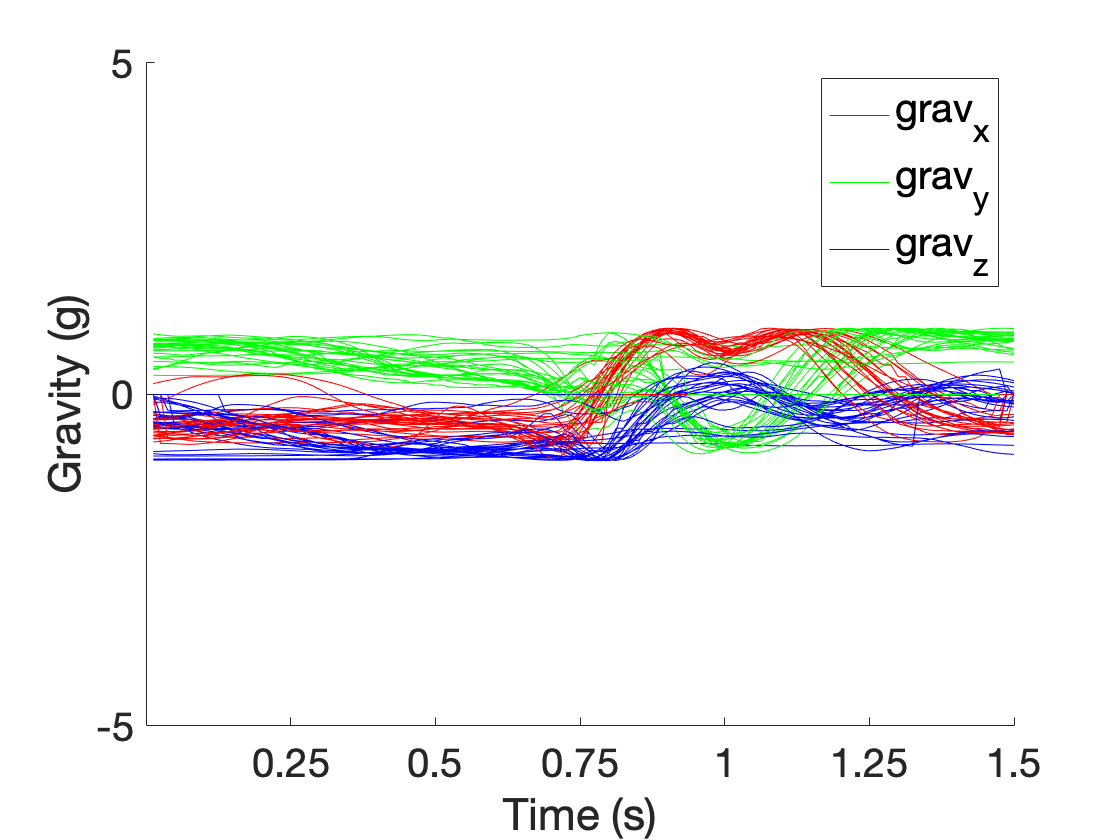

Filename46 = string(Path) + 'Player 17/M.Me.Bd.17.1.csv';
Filename47 = string(Path) + 'Player 17/M.Me.Bd.17.2.csv';
Filename51 = string(Path) + 'Player 17/M.Me.Bd.17.3.csv';
Filename56 = string(Path) + 'Player 16/M.E.Bd.16.csv';
Filename57 = string(Path) + 'Player 23/M.Me.Bd.23.1.csv';
Filename58 = string(Path) + 'Player 23/M.Me.Bd.23.2.csv';

files_bd = [Filename46,Filename47, Filename51, Filename56, Filename57, Filename58];

[AllbGyroX,AllbGyroY,AllbGyroZ,AllbAccelX,AllbAccelY,AllbAccelZ,AllbGravX,AllbGravY,AllbGravZ] = Compile_trial(files_bd, M, colaccX,colaccY,colaccZ,colgyroX,colgyroY,colgyroZ,colgravX,colgravY,colgravZ);

[baMax,baMin,baMean,baStd,baArea,bgMax,bgMin,bgMean,bgStd,bgArea,bgravMax,bgravMin,bgravMean,bgravStd,bgravArea] = MaxMin_trial(AllbGyroX,AllbGyroY,AllbGyroZ,AllbAccelX,AllbAccelY,AllbAccelZ,AllbGravX,AllbGravY,AllbGravZ);
[RacketSpeedAverage] = RacketSpeed(AllbGyroY, AllbGyroZ);

RacketSpeedAverage = 33.0794

[hSMS,hDMS,hmaxAZZ,hminAZZ,hGSMS,hGDMS,hmaxGZZ,hminGZZ] = features_misses(AllbAccelX,AllbAccelY,AllbAccelZ,AllbGravX,AllbGravY,AllbGravZ);

## Backhand Misses

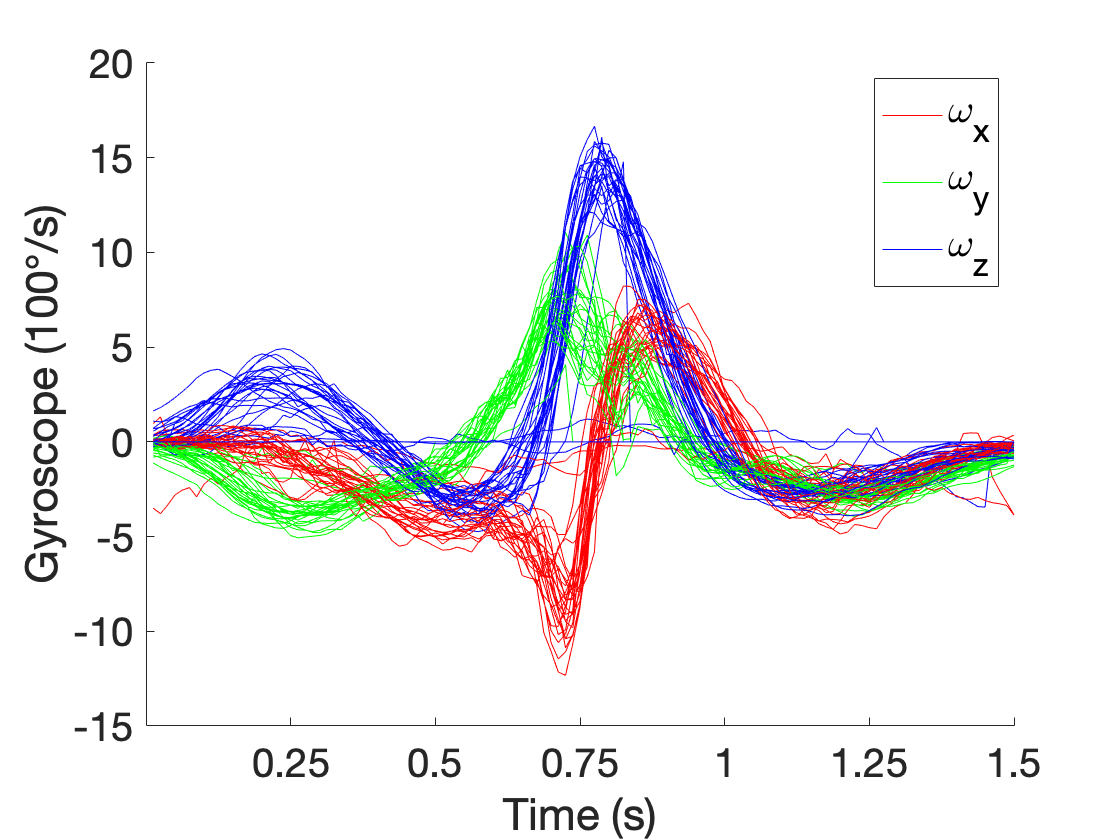

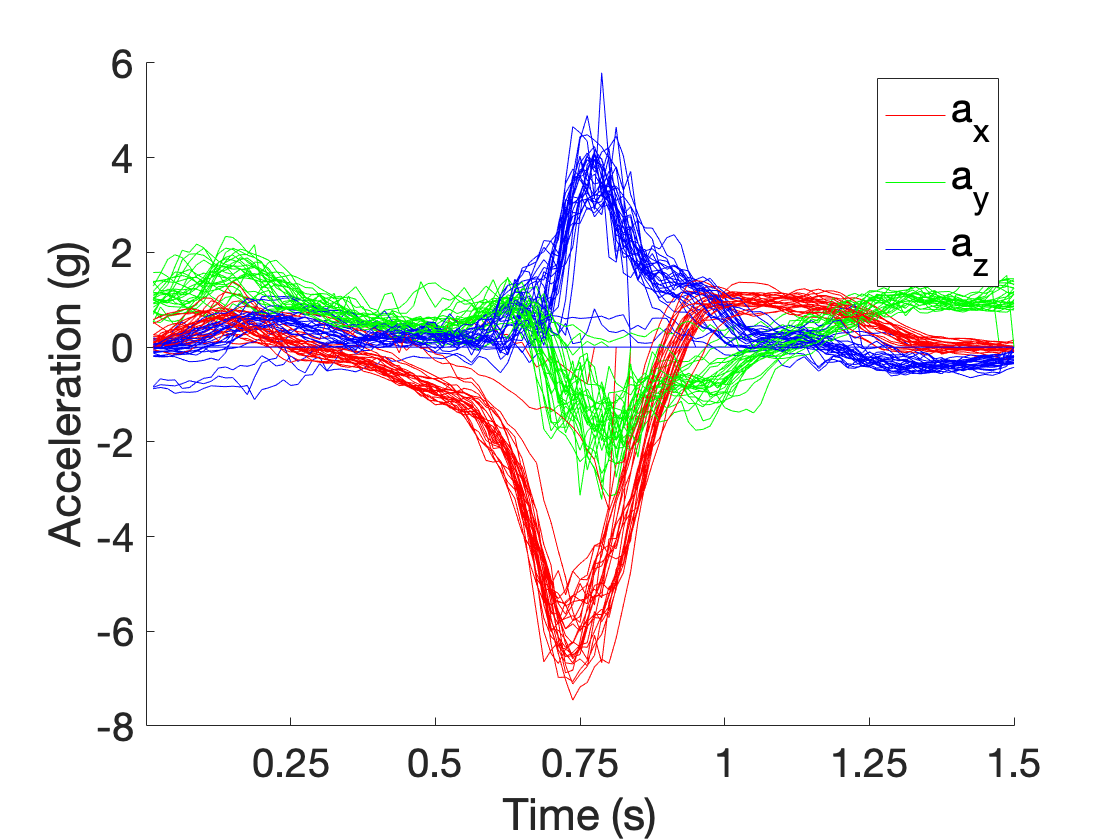

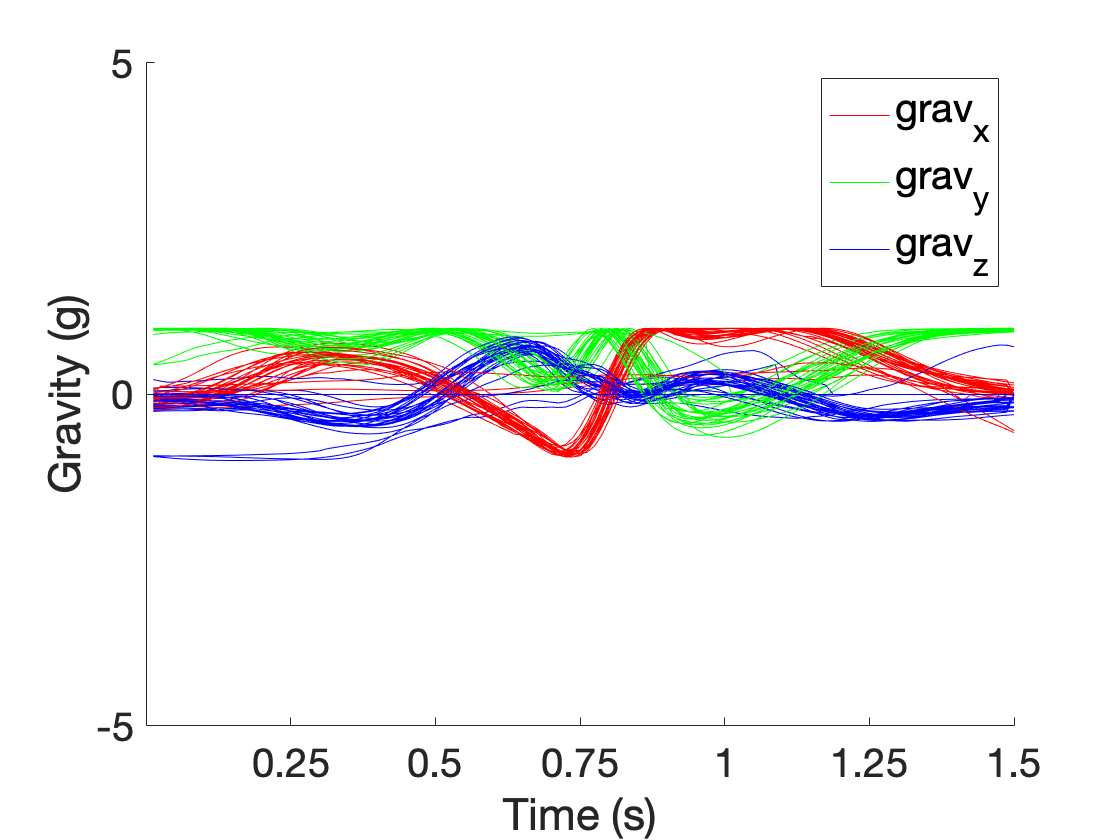

Filename1= string(Path) + 'Misses/Misses.5.csv';
Filename2= string(Path) + 'Misses/Misses.6.csv';
Filename3= string(Path) + 'Misses/Misses.7.csv';
Filename4= string(Path) + 'Misses/Misses.8.csv';

files_fd_Misses = [Filename1, Filename2, Filename3, Filename4];

[AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ] = Compile_trial(files_fd_Misses,32, colaccX,colaccY,colaccZ,colgyroX,colgyroY,colgyroZ,colgravX,colgravY,colgravZ);

[faMax,faMin,faMean,faStd,faArea,fgMax,fgMin,fgMean,fgStd,fgArea,fgravMax,fgravMin,fgravMean,fgravStd,fgravArea] = MaxMin_trial(AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ);
[RacketSpeedAverage] = RacketSpeed(AllfGyroY, AllfGyroZ);

RacketSpeedAverage = 37.9023

[mSMS,mDMS,mmaxAZZ,mminAZZ,mGSMS,mGDMS,mmaxGZZ,mminGZZ] = features_misses(AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ);

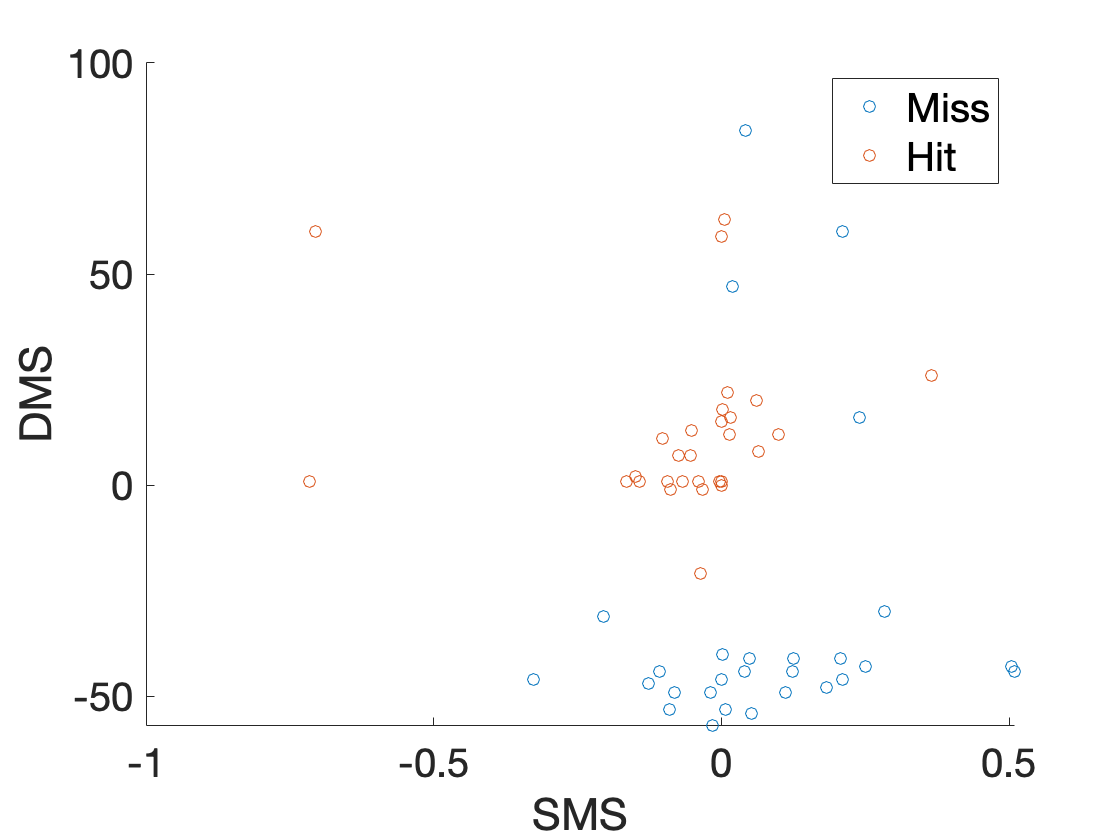

figure
scatter(mSMS, mDMS)
hold on
scatter(hSMS, hDMS)
xlabel('SMS','FontSize', 20); %x-axis label 
legend('Miss', 'Hit','FontSize', 20)
ylabel('DMS','FontSize', 20); %y-axis label
set(gca,'FontSize',20)
hold off

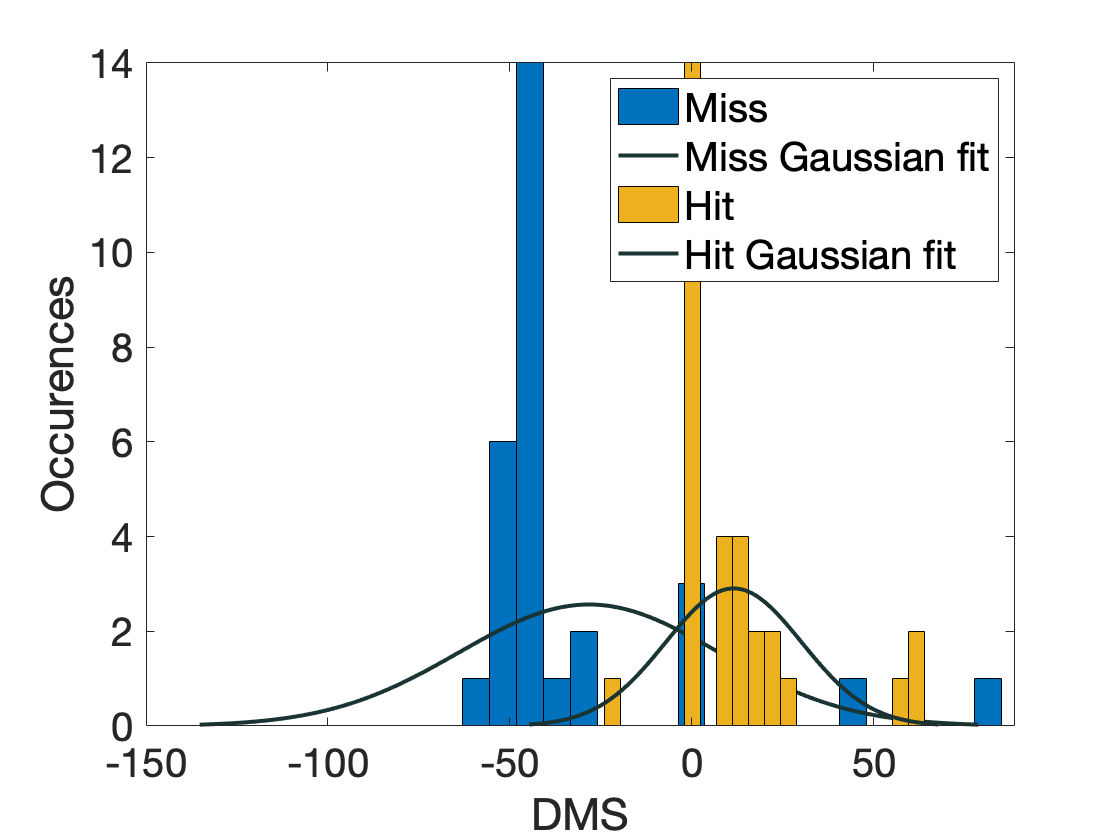

figure
m1 = histfit(mDMS,20);
m1(2).Color = [.1 .2 .2];
hold on
m2 = histfit(hDMS,20);
m2(2).Color = [.1 .2 .2];
xlabel('DMS','FontSize', 20); %x-axis label 
legend('Miss', 'Miss Gaussian fit', 'Hit','Hit Gaussian fit','FontSize', 20)
ylabel('Occurences','FontSize', 20); %y-axis label
set(gca,'FontSize',20)
hold off

mean(mDMS)

ans = -28.2581

mean(hDMS)

ans = 11.4839


mean(rmmissing(mSMS))

ans = 0.0709

mean(rmmissing(hSMS))

ans = -0.0608


std(mDMS)

ans = 35.6651

std(hDMS)

ans = 18.7276


std(rmmissing(mSMS))

ans = 0.1795

std(rmmissing(hSMS))

ans = 0.1969

[m, p] = chi2gof(mDMS,'nbins',32,'cdf',@normcdf)

m = 1

p = 0.0030

[h, p] = chi2gof(hDMS, 'nbins',32,'cdf',@normcdf)

h = 1

p = 6.4370e-04